# plotting NB spread in ISCs

conProx1 = load('C2-MAX_20190827 exp270 cx26flfl isc NB myo7a 25x close to ihc higher excitation_thresholds.mat');
conProx2 = load('C3-MAX_20190718 exp 239 cell 2 cx26flfl dapi myo7a NB_thresholds.mat');
conProx3 = load('C2-MAX_20200717 exp345 cell 3 cx26flfl myo7a NB 25x close to IHC higher excitation_thresholds.mat');
conProx4 = load('C2-MAX_20200815 exp 349 cell 1 myo7a streptavidin 555 25x_thresholds.mat');

conCreProx1 = load('C2-MAX_20201012 exp372 cell 3 cre+ control ISC myo7a strep 555 25x_thresholds.mat');
conCreProx2 = load('C2-MAX_20201012 exp372 cell 2 cre+ control ISC myo7a strep 555 25x_thresholds.mat');

conDist1 = load('C2-MAX_20190827 exp270 cx26flfl isc NB myo7a 25x mid dist higher excitation_thresholds.mat');
conDist2 = load('C2-MAX_20200717 exp345 cell 4 cx26flfl myo7a NB 25x far from IHC higher excitation_thresholds.mat')

conDist2 = struct with fields:
     lineProf: [664×1 double]
    pixelArea: 2.7402e+04


conDist3 = load('C2-MAX_20200717 exp345 cell 5 cx26flfl myo7a NB 25x mid distance higher excitation_thresholds.mat')

conDist3 = struct with fields:
     lineProf: [696×1 double]
    pixelArea: 3.3297e+04


conDist4 = load('C2-MAX_20200815 exp 349 cell 4 myo7a streptavidin 555 25x_thresholds.mat');
conDist5 = load('C2-MAX_20200815 exp 351 cell 6 myo7a streptavidin 555 25x_thresholds.mat');

ckoProx1 = load('C3-MAX_20190718 exp 239 cell 1 tecta cx26 dapi myo7a NB_thresholds.mat');
ckoProx2 = load('C3-MAX_20190711 exp234 tecta cx26 flfl cell 1 cochlea NB filled dapi cx26 streptavidin_thresholds.mat');
ckoProx3 = load('MAX_C3-20190711 exp234 tecta cx26 flfl cell 2 cochlea NB filled dapi cx26 streptavidin_thresholds.mat');
ckoProx4 = load('C2-MAX_20200717 exp345 cell 1 tecta cre cx26flfl myo7a NB 25x close to IHC_thresholds.mat');
ckoProx5 = load('C2-MAX_20200717 exp345 cell 7 tecta cre cx26flfl myo7a NB 25x close to IHC_thresholds.mat');
ckoProx6 = load('C2-MAX_20200815 exp 349 cell 2 myo7a streptavidin 555 25x_thresholds.mat');

ckoDist1 = load('C2-MAX_20190827 exp270 tecta cre cx26flfl isc NB myo7a 25x mid dist_thresholds.mat');
ckoDist2 = load('C2-MAX_20190827 exp270 tecta cre cx26flfl isc NB myo7a 25x mid dist prep 4_2_thresholds.mat');
ckoDist3 = load('C2-MAX_20190827 exp270 tecta cre cx26flfl isc NB myo7a 25x mid dist prep 4_1_thresholds.mat');
ckoDist4 = load('C2-MAX_20200815 exp 349 cell 3 myo7a streptavidin 555 25x_thresholds.mat');
ckoDist5 = load('C2-MAX_20201012 exp372 cell 6 CX26 CKO isc myo7a strep 555 25x_thresholds.mat');
ckoDist6 = load('C2-MAX_20201012 exp372 cell 7 CX26 CKO isc myo7a strep 555 25x_thresholds.mat');


conProx = [conProx1.pixelArea,conProx2.pixelArea,conProx3.pixelArea,conProx4.pixelArea,conCreProx1.pixelArea,conCreProx2.pixelArea];
ckoProx = [ckoProx1.pixelArea,ckoProx2.pixelArea,ckoProx3.pixelArea,ckoProx4.pixelArea,ckoProx5.pixelArea,ckoProx6.pixelArea];

conDist = [conDist1.pixelArea,conDist2.pixelArea,conDist3.pixelArea,conDist4.pixelArea,conDist5.pixelArea];
ckoDist = [ckoDist1.pixelArea,ckoDist2.pixelArea,ckoDist3.pixelArea,ckoDist4.pixelArea,ckoDist5.pixelArea,ckoDist6.pixelArea];

% plots

ylbl = ('Neurobiotin spread (um2)');
conditions = {'Control','Cx26 cKO'};
dim = [1 2];
fig1 = compare2(conProx,ckoProx,conditions,ylbl,dim)

   1.5137e-04



fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 381
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


ylim([0 50000])

% 

% plots

ylbl = ('Neurobiotin spread (um2)');
conditions = {'Control','Cx26 cKO'};
dim = [1 2];
fig2 = compare2(conDist,ckoDist,conditions,ylbl,dim)

not normal
    0.0043



fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 382
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


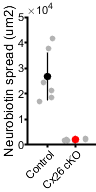

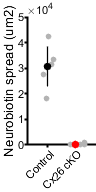

ylim([0 50000])

subP = handleTheSubplot({fig1,fig2},[1 2]);

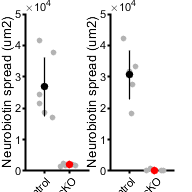

figQuality(subP,gca,[2 2])

%

% log plots 
logconProx = log10(conProx);
logckoProx = log10(ckoProx);

logconDist = log10(conDist);
logckoDist = log10(ckoDist); 

ylbl = ('Neurobiotin spread (um2)');
conditions = {'Control','Cx26 cKO'};
dim = [1 2];
[fig1 h p] = compare2(logconProx,logckoProx,conditions,ylbl,dim)

   2.1864e-08



fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 384
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 1

p = 2.1864e-08

p

p = 2.1864e-08

ylim([0 5])

ylbl = ('Neurobiotin spread (um2)');
conditions = {'Control','Cx26 cKO'};
dim = [1 2];
[fig2 h p] = compare2(logconDist,logckoDist,conditions,ylbl,dim)

not normal
    0.0043



fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 385
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p = 0.0043

p

p = 0.0043

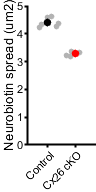

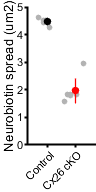

ylim([0 5])

subP = handleTheSubplot({fig1,fig2},[1 2]);

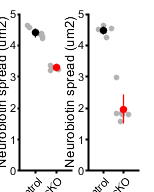

figQuality(subP,gca,[1.6 2])

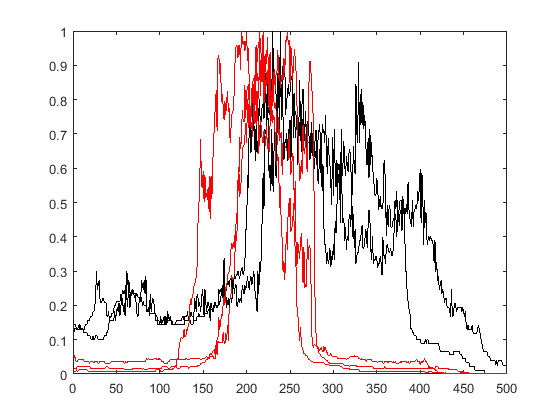

% plotting line profile 
% raw, normalized, averages

figure
plot([1:1:500],ckoProx1.lineProf(200:1:699)/max(ckoProx1.lineProf),'r')
hold on
plot([1:1:500],conProx2.lineProf(200:1:699)/max(conProx2.lineProf),'k')

plot([1:1:500],conProx1.lineProf(200:1:699)/max(conProx1.lineProf),'k')

plot([1:1:500],ckoProx2.lineProf(400:1:899)/max(ckoProx2.lineProf),'r')
plot([1:1:500],ckoProx3.lineProf(300:1:799)/max(ckoProx3.lineProf),'r')
hold off

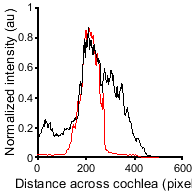

figure
meancKO = mean([(ckoProx1.lineProf(200:1:699)/max(ckoProx1.lineProf))';(ckoProx2.lineProf(400:1:899)/max(ckoProx2.lineProf))';(ckoProx3.lineProf(300:1:799)/max(ckoProx3.lineProf))'],1);
plot([1:1:500],medfilt1(meancKO),'r')
hold on
meanCon = mean([(conProx1.lineProf(200:1:699)/max(conProx1.lineProf))';(conProx2.lineProf(200:1:699)/max(conProx2.lineProf))'],1);
plot([30:1:500]-29,medfilt1(meanCon(30:1:500)),'k')
ylabel('Normalized intensity (au)');
xlabel('Distance across cochlea (pixels)');
figQuality(gcf,gca,[2 2])